# Result Analyze

close all;clear;clc;
addpath models/
load data/data_rat010_0615_spike_train_selected_with_delay.mat
load results/GLM_explore_H_1.mat
load results/GLM_sec_explore_H_1.mat
load results/ANN_explore_Nz.mat
load results/ANN_explore_H_1.mat
ANN_explore_H2 = load("results\ANN_explore_H_1_Nz_6.mat", "ANN_explore_H");
ANN_explore_H2 = ANN_explore_H2.ANN_explore_H;
% load results/ANN_explore_xi.mat

% % ANN xi
% % best, avrage, middle, number of less than 0.8?
% DBRtable = zeros(7,7,20);
% LTable = zeros(7,7,20);
% for xi1No=1:7
%   for xi2No=1:7
%     for index=1:20
%       DBRtable(xi1No, xi2No, index) = ANN_explore_xi(xi1No, xi2No, index).DBR;
%       LTable(xi1No, xi2No, index) = ANN_explore_xi(xi1No, xi2No, index).L;
%     end
%   end
% end
% xi_bestDBR = zeros(7,7);
% xi_bestL = zeros(7,7);
% xi_avrDBR = zeros(7,7);
% xi_avrL = zeros(7,7);
% xi_medDBR = zeros(7,7);
% xi_medL = zeros(7,7);
% xi_fairDBR = zeros(7,7);
% xi_fairL = zeros(7,7);
% for i=1:7
%   for j=1:7
%     xi_bestDBR(i, j) = min(DBRtable(i, j,:));
%     xi_bestL(i,j) = max(LTable(i,j,:));
%     xi_avrDBR(i, j) = mean(DBRtable(i, j,:));
%     xi_avrL(i,j) = mean(LTable(i,j,:));
%     xi_medDBR(i, j) = median(DBRtable(i, j,:));
%     xi_medL(i,j) = median(LTable(i,j,:));
%     xi_fairDBR(i, j) = sum(DBRtable(i, j,:)<0.75);
%     xi_fairL(i,j) = sum(LTable(i,j,:)>-15000);
%   end
% end
% xi_bestDBR
% xi_bestL
% xi_avrDBR
% xi_avrL
% xi_medDBR
% xi_medL
% xi_fairDBR
% xi_fairL

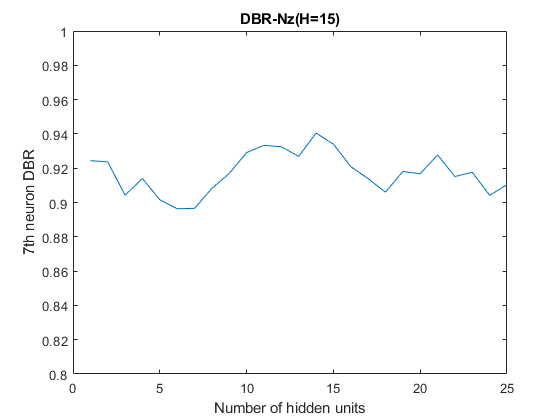

% ANN Nz-DBR
ANN_Nz_DBR = zeros(1,25);
Nzlist = 1:25;
for Nz=Nzlist
  bestDBR = Inf;
  ANN_DBR_list = getFieldArray(ANN_explore_Nz, "DBR", Nz);
  ANN_Nz_DBR(Nz)=min(ANN_DBR_list);
end
figure(1)
plot(Nzlist, ANN_Nz_DBR(Nzlist))
xlabel("Number of hidden units")
ylabel("7th neuron DBR")
ylim([0.8,1])
title(['DBR-Nz(H=', num2str(ANN_explore_Nz(5,1).H), ')'])

% % ANN Nz-L
% ANN_Nz_L = zeros(1,20);
% Nzlist = 1:20;
% for Nz=Nzlist
%   bestL = -Inf;
%   for i=1:ceil(Nz/5)*16
%     bestL = max(ANN_explore_Nz(Nz,i).L, bestL);
%   end
%   ANN_Nz_L(Nz)=bestL;
% end
% figure
% plot(Nzlist, ANN_Nz_L)
% xlabel("Number of hidden units")
% ylabel("7th neuron L")
% title("L-Nz(H=5)")
% % ANN Nz-L
% ANN_H_L = zeros(1,10);
% for H=1:10
%   bestL = -Inf;
%   for i=1:30
%     bestL = max(ANN_explore_H(H,i).L, bestL);
%   end
%   ANN_H_L(H)=bestL;
% end
% figure
% plot(1:10, ANN_H_L)
% xlabel("History length")
% ylabel("7th neuron L")
% title("L-H(Nz=10)")

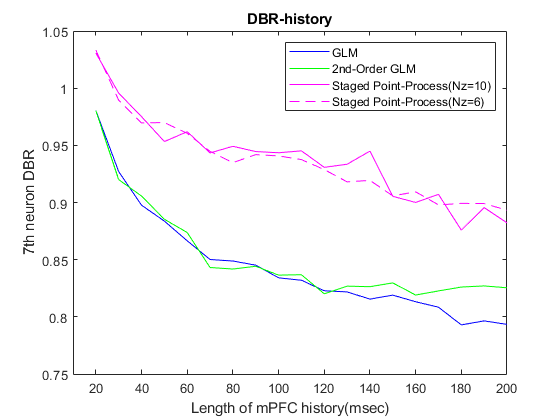

% get DBRs from differnt model result
GLM_sec_DBR = zeros(1,20);
GLM_DBR = zeros(1,20);
ANN_DBR = zeros(1,20);
ANN2_DBR = zeros(1,20);
% for i=1:16
%   GLM_sec_DBR(i) = GLM_sec_explore_H(i).DBR;
% end
for H=2:20
  GLM_DBR(H)     = GLM_explore_H(H).DBR;
  GLM_sec_DBR(H) = GLM_sec_explore_H(H).DBR;
  ANN_DBR_list = getFieldArray(ANN_explore_H, "DBR", H);
  ANN_DBR(H) = min(ANN_DBR_list);
  ANN_DBR_list = getFieldArray(ANN_explore_H2, "DBR", H);
  ANN2_DBR(H) = min(ANN_DBR_list);
end
% plot DBR-history result
figure(2)
plot(20:10:200, GLM_DBR(2:20), 'b')
hold on
plot(20:10:200, GLM_sec_DBR(2:20), 'g')
plot(20:10:200, ANN_DBR(2:20), 'm')
plot(20:10:200, ANN2_DBR(2:20), '--m')
hold off
legend("GLM", "2nd-Order GLM", ['Staged Point-Process(Nz=', num2str(ANN_explore_H(1,1).Nz), ')'], ['Staged Point-Process(Nz=', num2str(ANN_explore_H2(2,1).Nz), ')'])
xlabel("Length of mPFC history(msec)")
xlim([10 200])
ylabel("7th neuron DBR")
title("DBR-history")

Take history = 100msec, kernel size = 0.3s

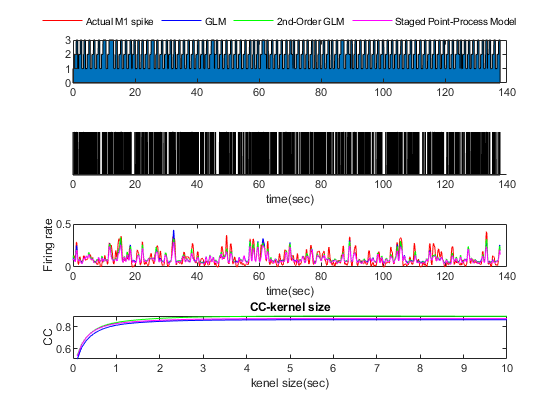

H=15;
% get GLM params & test result
W     = GLM_explore_H(H).W;
M1Idx = GLM_explore_H(H).M1Idx;
[~,~,~,trainX,~,testX,trainY,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,H);
GLMtestLambdaYpre = GLMmodel(testX, W);
GLMtrainLambdaYpre = GLMmodel(trainX,W);
GLMccListTest = zeros(1, 1000/10);
GLMccListTrain = zeros(1, 1000/10);
% smooth result
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLMccListTest(kernelSize/10) = cc(2);
  smoothedLambda    = gaussianSmooth(trainY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMtrainLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLMccListTrain(kernelSize/10) = cc(2);
end
% 2nd Order GLM
W     = GLM_sec_explore_H(H).W;
M1Idx = GLM_sec_explore_H(H).M1Idx;
lagnum = GLM_sec_explore_H(H).lagnum;
lagalpha = GLM_sec_explore_H(H).lagalpha;
order = ['vm2-',num2str(lagnum),'-',num2str(lagalpha)];
[~,~,~,trainX,~,testX,trainY,~,testY,trainEvent,~,testEvent] = splitDataAdvance(order,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,H);
GLMsectestLambdaYpre = GLMmodel(testX, W);
GLMsectrainLambdaYpre = GLMmodel(trainX, W);
GLM_sec_ccListTest = zeros(1, 1000/10);
GLM_sec_ccListTrain = zeros(1, 1000/10);
% smooth
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLM_sec_ccListTest(kernelSize/10) = cc(2);
  smoothedLambda    = gaussianSmooth(trainY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMsectrainLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLM_sec_ccListTrain(kernelSize/10) = cc(2);
end
% ANN
W     = ANN_explore_Nz(15,24).W;
M1Idx = ANN_explore_Nz(15,24).M1Idx;
Nz    = ANN_explore_Nz(15,24).Nz;
[~,~,~,trainX,~,testX,trainY,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,H);
[~, Nx] = size(testX);
ANNtestLambdaYpre  = ANNmodel(testX,  W, Nx, Nz);
ANNtrainLambdaYpre = ANNmodel(trainX, W, Nx, Nz);
ANNccListTest = zeros(1, 1000/10);
ANNccListTrain = zeros(1, 1000/10);
% smooth
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  ANNccListTest(kernelSize/10) = cc(2);
  smoothedLambda    = gaussianSmooth(trainY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(ANNtrainLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  ANNccListTrain(kernelSize/10) = cc(2);
end

% optimal smooth kernel size result
kernelSize = 100;
smoothedLambda = gaussianSmooth(trainY, kernelSize);
smoothedGLMLambdaPre = gaussianSmooth(GLMtrainLambdaYpre, kernelSize);
smoothedGLMsecLambdaPre = gaussianSmooth(GLMsectrainLambdaYpre, kernelSize);
smoothedANNLambdaPre = gaussianSmooth(ANNtrainLambdaYpre, kernelSize);

% display results
spikeLength = length(trainY);
index = 1:spikeLength;
t = index/100;
% t = 45:0.01:75;
% index = 4500:7500;
figure("Name", "Train")
subplot(4,1,1)
area((1:length(trainEvent))/100, trainEvent)
% area(t, trainEvent(index))
% real spike
subplot(4,1,2)
area(t, trainY(index))
xlabel("time(sec)")
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
% smoothed results
subplot(4,1,3)
h{1} = plot(t, smoothedLambda(index), 'r');
hold on
h{2} = plot(t, smoothedGLMLambdaPre(index), 'b');
h{3} = plot(t, smoothedGLMsecLambdaPre(index), 'g');
h{4} = plot(t, smoothedANNLambdaPre(index), 'm');
hold off
xlabel("time(sec)")
ylabel("Firing rate")
% cc analyze
subplot(4,1,4)
plot(0.1:0.1:10, GLMccListTrain, 'b')
hold on
plot(0.1:0.1:10, GLM_sec_ccListTrain, 'g')
plot(0.1:0.1:10, ANNccListTrain, 'm');
hold off
xlabel("kenel size(sec)")
xlim([0 10])
ylabel("CC")
title("CC-kernel size")
legend([h{1}; h{2}; h{3}; h{4}], "Actual M1 spike", "GLM", "2nd-Order GLM", ...
  "Staged Point-Process Model", "Position",[0.5  0.95  0  0], ...
  "Box","off", "Orientation","horizontal")

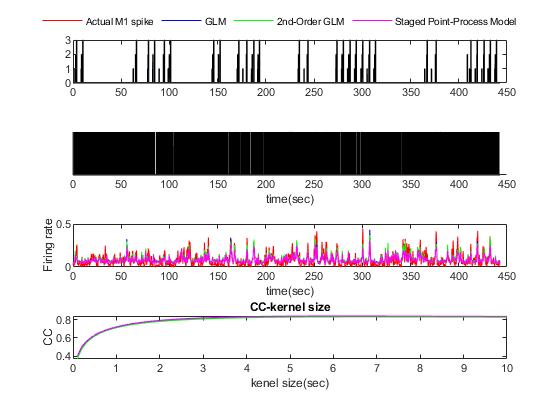

% optimal smooth kernel size result
kernelSize = 100;
smoothedLambda = gaussianSmooth(testY, kernelSize);
smoothedGLMLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
smoothedGLMsecLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
smoothedANNLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);

% display results
spikeLength = length(testY);
index = 1:spikeLength;
t = index/100;
% t = 240:0.01:280;
% index = 24000:28000;
figure("Name", "Test")
subplot(4,1,1)
area((1:length(testEvent))/100, testEvent)
% area(t, testEvent(index))
% real spike
subplot(4,1,2)
area(t, testY(index))
xlabel("time(sec)")
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
% smoothed results
subplot(4,1,3)
h{1} = plot(t, smoothedLambda(index), 'r');
hold on
h{2} = plot(t, smoothedGLMLambdaPre(index), 'b');
h{3} = plot(t, smoothedGLMsecLambdaPre(index), 'g');
h{4} = plot(t, smoothedANNLambdaPre(index), 'm');
xlabel("time(sec)")
ylabel("Firing rate")
% cc analyze
subplot(4,1,4)
plot(0.1:0.1:10, GLMccListTest, 'b')
hold on
plot(0.1:0.1:10, GLM_sec_ccListTest, 'g')
plot(0.1:0.1:10, ANNccListTest, 'm');
hold off
xlabel("kenel size(sec)")
xlim([0 10])
ylabel("CC")
title("CC-kernel size")
legend([h{1}; h{2}; h{3}; h{4}], "Actual M1 spike", "GLM", "2nd-Order GLM", ...
  "Staged Point-Process Model", "Position",[0.5  0.95  0  0], ...
  "Box","off", "Orientation","horizontal")

% figure
% hold on
% for i=1:800
%   [Nz, idx] = getParamIndex(i);
%   LHistory = ANN_explore_Nz(Nz,idx).LHistory;
%   LHistory(LHistory==0) = nan;
%   h=plot(LHistory);
%   set(h, 'color', [i/800, i*i/640000, sqrt(i)/sqrt(800)])
% end
% hold off
% figure
% hold on
% for i=1:200
%   LHistory = ANN_explore_H(i).LHistory;
%   LHistory(LHistory==0) = nan;
%   h=plot(LHistory);
%   set(h, 'color', [i/200, i*i/40000, sqrt(i)/sqrt(200)])
% end
% hold off

% ANN
W     = ANN_explore_H(3,13).W;
M1Idx = ANN_explore_H(3,13).M1Idx;
Nz    = ANN_explore_H(3,13).Nz;
[~,~,~,trainX,~,testX,trainY,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,H);
[~, Nx] = size(testX);
ANNtestLambdaYpre  = ANNmodel(testX,  W, Nx, Nz);

Index exceeds the number of array elements (171).

Error in ANNmodel (line 4)
w = reshape(W(1:Nx*Nz), Nx, Nz)';

% ANNtrainLambdaYpre = ANNmodel(trainX, W, Nx, Nz);

smoothedANNLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);
figure
plot(t, smoothedANNLambdaPre(index), 'g');

W     = ANN_explore_H(19,23).Whis(89,:);
M1Idx = ANN_explore_H(19,23).M1Idx;
Nz    = ANN_explore_H(19,23).Nz;
[~,~,~,trainX,~,testX,trainY,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,19);
[~, Nx] = size(trainX);
ANNtestLambdaYpre  = ANNmodel(trainX,  W, Nx, Nz);
% ANNtrainLambdaYpre = ANNmodel(trainX, W, Nx, Nz);

smoothedANNLambdaPre = gaussianSmooth(ANNtestLambdaYpre, 50);
smoothedLambda = gaussianSmooth(trainY, 50);
t = 55:0.01:100;
index = 5500:10000;
figure
plot(t, smoothedANNLambdaPre(index), 'b');
hold on
plot(t, smoothedLambda(index), 'r');
hold off

for H=1:15
  [trainLen, valLen, testLen, trainX, valX, testX, trainY, valY, testY, trainEvent, valEvent, testEvent] = splitDataAdvance(2,mPFCspike,M1spike(:,1),eventTrain,optimalDelay(1),segTrain,H);
  save(['data\splitedData\secondOrder_', num2str(H), '.mat'], ...
      "trainLen", "valLen", "testLen", ...
      "trainX", "valX", "testX", ...
      "trainY", "valY", "testY", ...
      "trainEvent", "valEvent", "testEvent")
end